# Battery UKF

- run this script, no need to load anything in the workspace

addpath fcns;
out = sim('batteryMine');

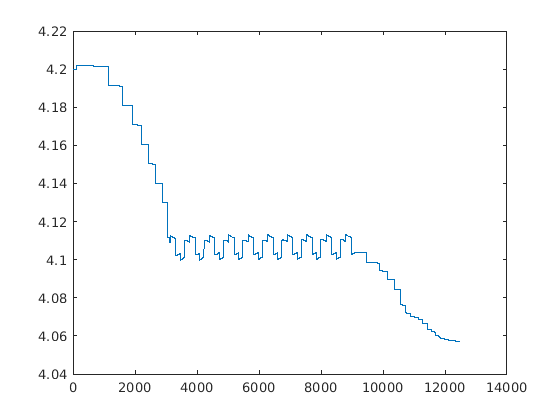

% sim('batteryMine_r2018a');
voltage = out.voltage.Data;
current = out.current.Data;
time = out.tout;
soc = out.soc.Data;
plot(voltage);


dt = time(2) - time(1); %.01
dt = dt;
%voltage = voltage / 3;


% Reserve storage for computed results, for plotting
soc_hat   = zeros(size(soc));
soc_bound = zeros(size(soc));
v_hat     = zeros(size(voltage));
v_noisy   = zeros(size(voltage));

% Covariance values
sigma_x = diag([100 1 .01]); % uncertainty of initial state
sigma_v = .3; % Uncertainty of voltage sensor, output equation
sigma_w = 4; % Uncertainty of current sensor, state equation

% Create vars structure and initialisoce variables using first
% voltage measurement and first temperature measurement
vars = initUKF(voltage(1),sigma_x,sigma_v,sigma_w,batteryParams);

soc: 
     1




% Now, enter loop for remainder of time, wgammaere we update tgammae uf
% once per sample interval
for k = 1:length(voltage),
  v_noisy(k) = normrnd(voltage(k), .03); % "measure" voltage
  i = normrnd(current(k), .0125); % "measure" current
  
  % Update SOC (and otgammaer battery states)
  [soc_hat(k),soc_bound(k),vars,v_hat(k)] = iterUKF(v_noisy(k),i,dt,vars);
  % update waitbar periodically, but not too often (slow procedure)
  if mod(k,1000)==0,
    fprintf('  Completed %d out of %d iterations...\n',k,length(voltage));
  end  
end

  Completed 1000 out of 12501 iterations...
  Completed 2000 out of 12501 iterations...
  Completed 3000 out of 12501 iterations...
  Completed 4000 out of 12501 iterations...
  Completed 5000 out of 12501 iterations...
  Completed 6000 out of 12501 iterations...
  Completed 7000 out of 12501 iterations...
  Completed 8000 out of 12501 iterations...
  Completed 9000 out of 12501 iterations...
  Completed 10000 out of 12501 iterations...
  Completed 11000 out of 12501 iterations...
  Completed 12000 out of 12501 iterations...


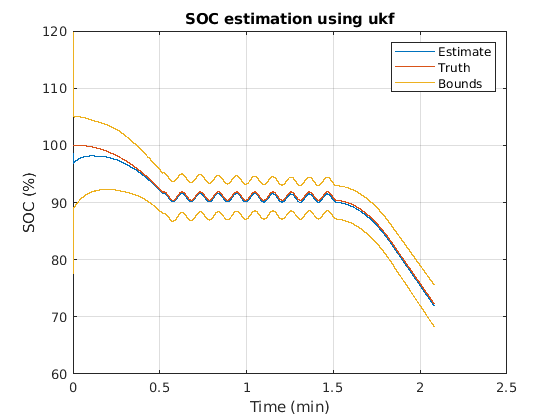


f1 = figure(1);clf;
plot(time/60,100*soc_hat,time/60,100*soc); hold on
plot([time/60; NaN; time/60],[100*(soc_hat+soc_bound); NaN; 100*(soc_hat-soc_bound)]);
title('SOC estimation using ukf'); grid on
xlabel('Time (min)'); ylabel('SOC (%)'); legend('Estimate','Truth','Bounds');
hold off;

fprintf('RMS SOC estimation error = %g%%\n',sqrt(mean((100*(soc-soc_hat)).^2)));

RMS SOC estimation error = 0.665935%


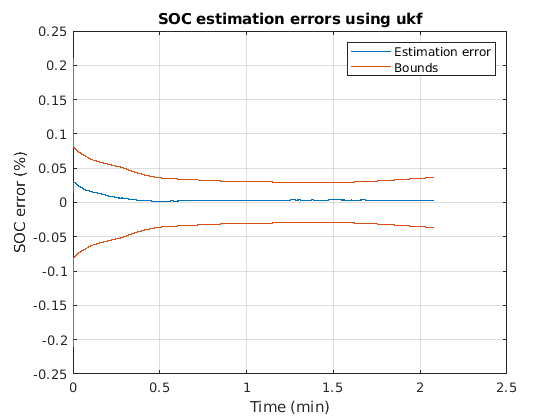

f2 = figure(2); clf;
plot(time/60,(soc-soc_hat)); hold on
plot([time/60; NaN; time/60],[soc_bound; NaN; -soc_bound]);
title('SOC estimation errors using ukf');
xlabel('Time (min)'); ylabel('SOC error (%)'); 
legend('Estimation error','Bounds'); 
grid on;
hold off;


idx = find(abs(soc-soc_hat)>soc_bound);
fprintf('Percent of time error outside bounds = %g%%\n',length(idx)/length(soc)*100);

Percent of time error outside bounds = 0%


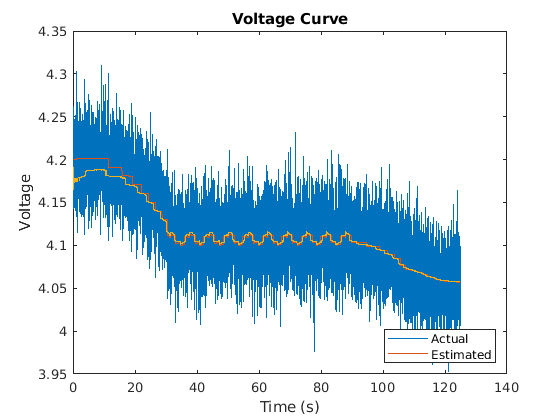

f3 = figure(3); clf;
plot(time, v_noisy);
hold on;
plot(time,voltage);
plot(time,v_hat);
legend('Actual', 'Estimated', 'Location', "southeast");
hold off;
title("Voltage Curve");
ylabel("Voltage");
xlabel("Time (s)");

function vars = initUKF(v0,sigma_x,sigma_v,sigma_w,battery)

  % currentnitial state description
  ir0    = 0;                           
  gamma0 = 0;                           
  SOC0   = getSOC(round(v0,2),battery) / 100.0;  
  disp("soc: ");
  disp(SOC0);
  
  vars.ir_idx    = 1;
  vars.gamma_idx = 2;
  vars.soc_idx   = 3;
  
  vars.x_hat  = [ir0 gamma0 SOC0]'; % initial state
  % Covariance values
  vars.sigma_x = sigma_x;
  vars.sigma_v = sigma_v;
  vars.sigma_w = sigma_w;
  vars.sigma_noise = real(chol(diag([sigma_w; sigma_v]),'lower'));
  vars.bump_val = 5;
  
  % ukf specific parameters
  x_len = length(vars.x_hat); 
  y_len = 1; 
  u_len = 1; 
  w_len = size(sigma_w,1); 
  v_len = size(sigma_v,1); 
  aux_len = x_len+w_len+v_len; 
  
  vars.x_len = x_len; % state-vector length
  vars.y_len = y_len; % measurement-vector length
  vars.u_len = u_len; % input-vector length
  vars.w_len = w_len; % process-noise-vector length
  vars.v_len = v_len; % sensor-noise-vector length
  vars.aux_len = aux_len;     % augmented-state-vector length
  
  gamma            = 3;
  vars.gamma       = gamma; % ukf/CDF tuning factor  
  mu_weights       = (gamma^2-aux_len)/(gamma^2); % weighting factors when computing mean
  cov_weights      = 1/(2*gamma^2);   % and covariance
  vars.mu_weights  = [mu_weights; cov_weights*ones(2*aux_len,1)]; % mean
  vars.cov_weights = vars.mu_weights;  % covar

  % previous value of current
  vars.u_old  = 0;
  vars.u_sign = 0;
  
  % store battery data structure too
  vars.battery = battery;
end  


function [soc,soc_bound,vars,y_hat] = iterUKF(voltage,current,dt,vars)
    % get params
    battery = vars.battery;
    n  = battery.n;
    Q  = battery.Q;
    G  = battery.G;
    M0 = battery.M0;
    M  = battery.M;
    R0 = battery.R0;
    R  = battery.R;
    RC = exp(-dt/abs(battery.RC))';
    
    if current<0, current=current*n; end;
    
    % Get data stored in vars structure
    sigma_x = vars.sigma_x;
    x_hat   = vars.x_hat;
    x_len   = vars.x_len;
    w_len   = vars.w_len;
    v_len   = vars.v_len;
    aux_len = vars.aux_len;
    
    sigma_noise = vars.sigma_noise;
    cov_weights = vars.cov_weights;
    
    ir_idx    = vars.ir_idx;
    gamma_idx = vars.gamma_idx;
    soc_idx   = vars.soc_idx;
    
    if abs(current)>Q/100
        vars.u_sign = sign(current); 
    end
    
    u_sign = sign(current);% vars.u_sign;
    
    
    % create augmented sigma_x and x_hat
    [sigma_x_aux,p] = chol(sigma_x,'lower'); 
    if p>0
        fprintf('Cholesky error.  Recovering...\n');
        diag_sigma_x = abs(diag(sigma_x));
        sigma_x_aux = diag(max(SQRT(diag_sigma_x),SQRT(vars.sigma_w)));
    end

    sigma_x_aux=[real(sigma_x_aux) zeros([x_len w_len+v_len]); zeros([w_len+v_len x_len]) sigma_noise];
    x_hat_aux = [x_hat; zeros([w_len+v_len 1])];
    % NOTE: sigma_x_aux is lower-triangular
    
    % calculate sigma points
    aux_state_mat = x_hat_aux(:,ones([1 2*aux_len+1])) + ...
       vars.gamma*[zeros([aux_len 1]), sigma_x_aux, -sigma_x_aux];
    
    % update state estimate 
    x_hat_pre = stateEqn(aux_state_mat(1:x_len,:),current,aux_state_mat(x_len+1:x_len+w_len,:)); 
    x_hat = x_hat_pre*vars.mu_weights;
    
    % Step 1b: Error covariance time update
    %          - Compute weighted covariance
    %            (strange indexing of x_hat to avoid "repmat" call)
    cov_pre = x_hat_pre - x_hat(:,ones([1 2*aux_len+1]));
    sigma_x= cov_pre*diag(cov_weights)*cov_pre';
  
    % Step 1c: Output estimate
    %          - Compute weighted output estimate y_hat()
    y = voltage;
    Y = outputEqn(x_hat_pre,current,aux_state_mat(x_len+w_len+1:end,:),battery);
    y_hat = Y*vars.mu_weights;
    
    % Step 2a: Estimator gain matrix
    residual = Y - y_hat(:,ones([1 2*aux_len+1]));
    innov = cov_pre*diag(cov_weights)*residual';
    sigma_y = residual*diag(cov_weights)*residual';
    K = innov/sigma_y; 
    
    % Step 2b: State estimate measurement update
    r = y - y_hat; % residual.  Use to check for sensor errors...
    if r^2 > 100*sigma_y
        K(:,1)=0.0; 
    end 
    
    x_hat = x_hat + K*r; 
    x_hat(soc_idx)   = min(1.05,max(-0.05,x_hat(soc_idx)));
    x_hat(gamma_idx) = min(1,max(-1,x_hat(gamma_idx)));

    % Step 2c: Error covariance measurement update
    sigma_x= sigma_x- K*sigma_y*K';
    [~,S,V] = svd(sigma_x);
    HH = V*S*V';
    sigma_x= (sigma_x+ sigma_x' + HH + HH')/4; % maintain robustness
    
    % Q-bump code, bump up sigma_x if its performing bad
    if r^2>4*sigma_y 
        fprintf('Bumping sigmax\n');
        sigma_x(soc_idx,soc_idx) = sigma_x(soc_idx,soc_idx)*vars.bump_val;
    end
    
    % Save data in vars structure for next time...
    vars.sigma_x = sigma_x;
    vars.x_hat   = x_hat;
    
    soc = x_hat(soc_idx);
    soc_bound = 3*sqrt(sigma_x(soc_idx,soc_idx));
    
    y_hat = y_hat;

% Calculate new states for all of tgammae old state vectors in xold.  
  function xnew = stateEqn(xold,current,xnoise)
    current = current + xnoise; % noise adds to current
    H_mat   = exp(-abs(current*G*dt/(3600*Q)));  % hysteresis factor
    
    xnew              = 0*xold;
    xnew(ir_idx,:)    = RC*xold(ir_idx,:) + (1-diag(RC))*current;
    xnew(gamma_idx,:) = H_mat.*xold(gamma_idx,:) + (H_mat-1).*sign(current);
    xnew(soc_idx,:)  = xold(soc_idx,:) - current/3600/Q;
    xnew(gamma_idx,:) = min(1,max(-1,xnew(gamma_idx,:)));
    xnew(soc_idx,:)  = min(1.05,max(-0.05,xnew(soc_idx,:)));
  end

  % Calculate cell output voltage for all of state vectors in x_hat
  function y_hat = outputEqn(x_hat,current,ynoise,battery)
    y_hat = getOCV_UKF(x_hat(soc_idx,:),battery);
    y_hat = y_hat + M*x_hat(gamma_idx,:) + M0*u_sign;
    y_hat = y_hat - R*x_hat(ir_idx,:) - R0*current + ynoise(1,:);
  end

  % "Safe" square root
  function X = SQRT(x)
    X = sqrt(max(0,x));
  end
end





